# CNN

Author: Christopher Couture Del Valle

Date: 11/22/2021

## Load the Dataset

In this sections we load the images required for training and testing

% Clear workspace
clear; close all; clc;

% Image datastore
imds = imageDatastore("/Users/chris/Downloads/cell_images/",'IncludeSubfolders',true, "LabelSource","foldernames")

imds =   ImageDatastore with properties:

                       Files: {
                              ' .../cell_images/Parasitized/C100P61ThinF_IMG_20150918_144104_cell_162.png';
                              ' .../cell_images/Parasitized/C100P61ThinF_IMG_20150918_144104_cell_163.png';
                              ' .../cell_images/Parasitized/C100P61ThinF_IMG_20150918_144104_cell_164.png'
                               ... and 27555 more
                              }
                     Folders: {
                              '/Users/chris/Downloads/cell_images'
                              }
                      Labels: [Parasitized; Parasitized; Parasitized ... and 27555 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     


%Total count of each class
total_count = countEachLabel(imds)

total_count = 2×2 table
       Label       Count
    ___________    _____

    Parasitized    13779
    Uninfected     13779


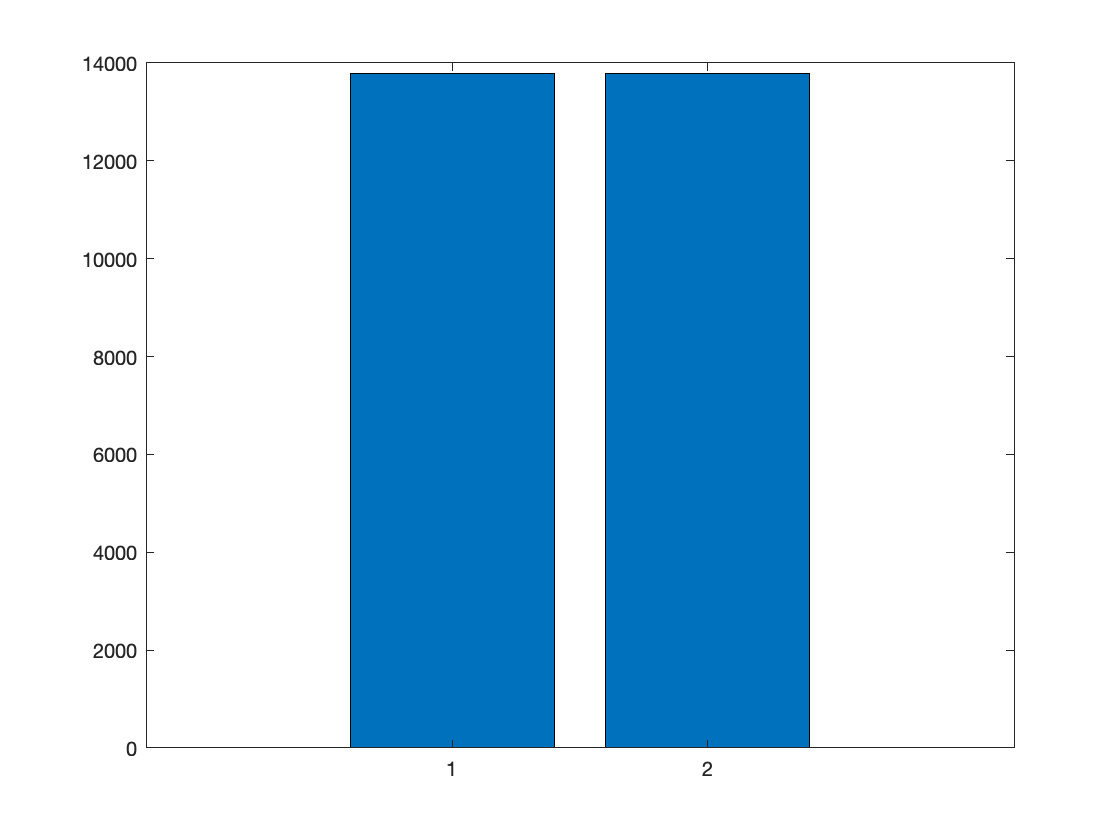


%Visualize both classes in bar chart
bar(total_count.Count)

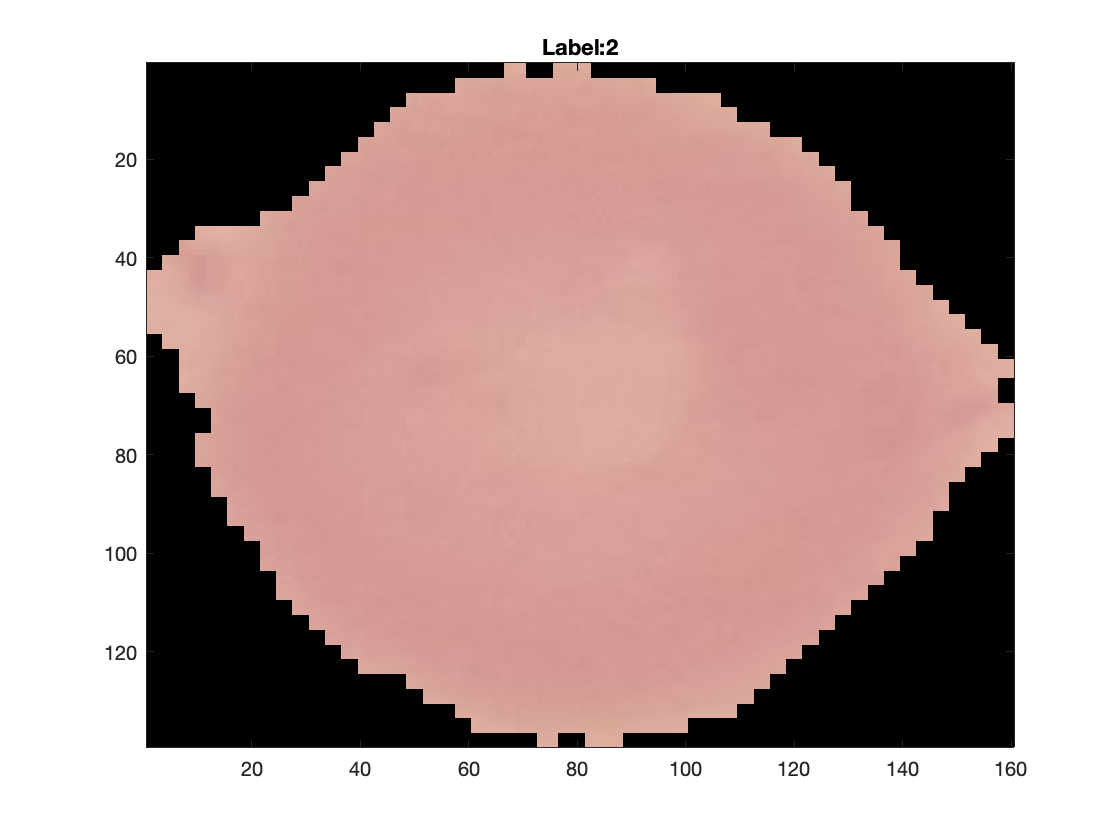


%Visualize image from each label
%Better suited for instances with more labels, included for 
%proof of concept

double_labels = double(imds.Labels);
for idx=1:length(unique(imds.Labels))
    
    %Find one index of each image
    current_label_idx = find(double_labels==idx,1,"first");
    
    %Read the file
    I = readimage(imds,current_label_idx);
    
    figure(1);
    imagesc(I);
    title(sprintf('Label:%d',double_labels(current_label_idx)));
    %Long pause since there are only two images
    pause(2.5);
end

## Visualize the Images

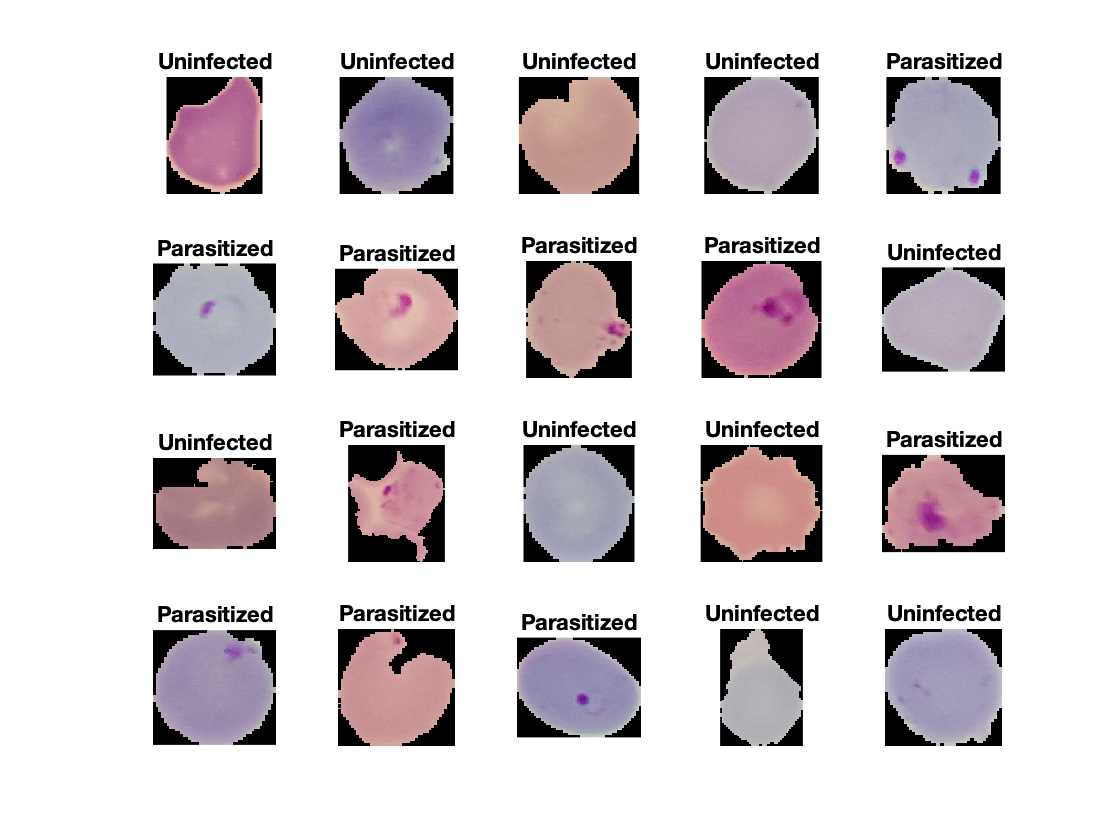

% Number of Images
num_images=length(imds.Labels);

% Visualize random 20 images
perm=randperm(num_images,20);
figure;
for idx=1:20

 subplot(4,5,idx);
 imshow(imread(imds.Files{perm(idx)}));
 title(sprintf('%s',imds.Labels(perm(idx))))

end

## Visualize Preprocessed Images

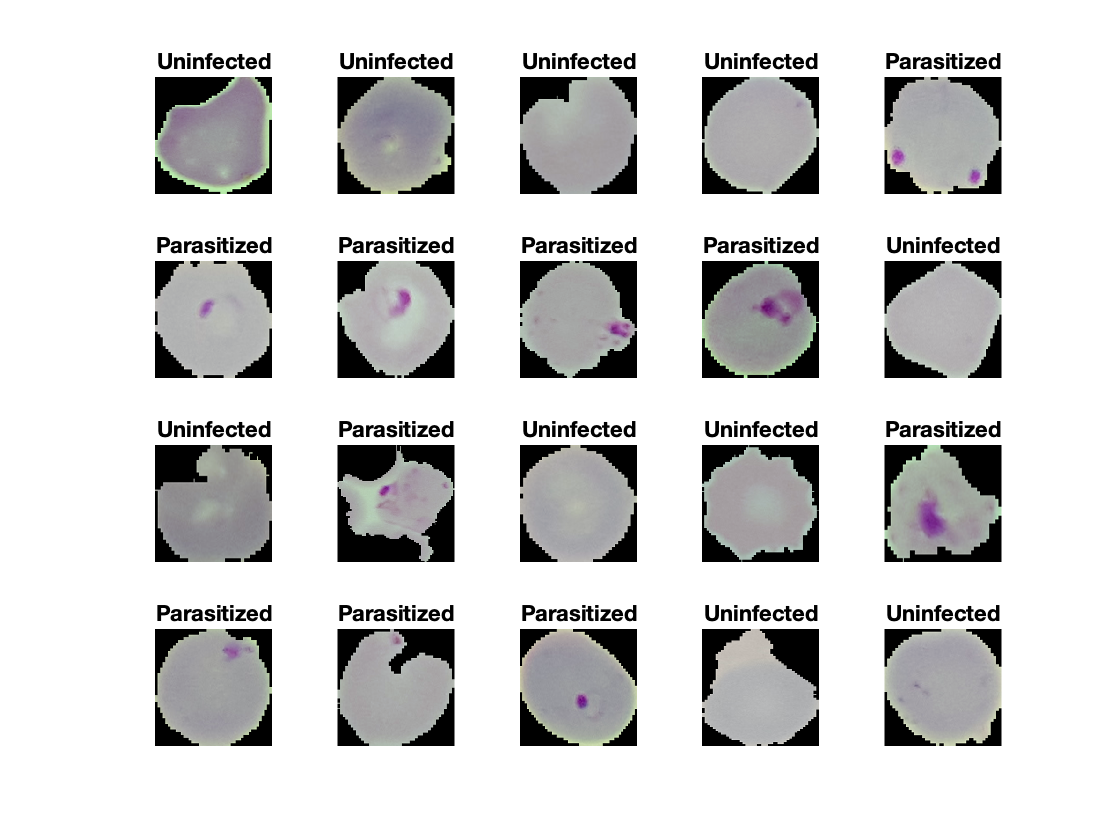

figure;

for idx=1:20
 subplot(4,5,idx);
 imshow(preprocess_malaria_images(imds.Files{perm(idx)},[250 250]))
 title(sprintf('%s',imds.Labels(perm(idx))))
end

## Training and Validation Dataset

% Split the Training and Testing Dataset
train_percent=0.90;
[imdsTrain,imdsTest]=splitEachLabel(imds,train_percent,'randomize');
% Split the Training and Validation
valid_percent=0.1;
[imdsValid,imdsTrain]=splitEachLabel(imdsTrain,valid_percent,'randomize');

train_split=countEachLabel(imdsTrain);
valid_count=countEachLabel(imdsValid);
test_split=countEachLabel(imdsTest);

## Deep CNN

Training on single CPU.
Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:15 |       50.00% |       50.00% |       3.0271 |       6.5417 |          0.0010 |


|       1 |          50 |       00:00:35 |       85.94% |              |       0.4296 |              |          0.0010 |


|       1 |         100 |       00:01:04 |       92.19% |       92.02% |       0.2233 |       0.2266 |          0.0010 |


|       1 |         150 |       00:01:24 |       90.62% |              |       0.3063 |              |          0.0010 |


|       1 |         200 |       00:01:52 |       98.44% |       94.19% |       0.0965 |       0.1911 |          0.0010 |


|       1 |         250 |       00:02:13 |       96.88% |              |       0.0715 |              |          0.0010 |


|       1 |         300 |       00:02:41 |       92.19% |       94.80% |       0.1714 |       0.1426 |          0.0010 |


|       2 |         350 |       00:03:02 |       96.88% |              |       0.1255 |              |          0.0010 |


|       2 |         400 |       00:03:24 |       96.88% |       95.20% |       0.1148 |       0.1474 |          0.0010 |


|       2 |         450 |       00:03:39 |       98.44% |              |       0.0632 |              |          0.0010 |


|       2 |         500 |       00:04:01 |       98.44% |       94.56% |       0.0910 |       0.1569 |          0.0010 |


|       2 |         550 |       00:04:16 |       93.75% |              |       0.1427 |              |          0.0010 |


|       2 |         600 |       00:04:44 |       93.75% |       95.16% |       0.1910 |       0.1569 |          0.0010 |


|======================================================================================================================|


deepnet =   SeriesNetwork with properties:

         Layers: [27×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


img_size=[32 32];

% imdsTrain.ReadFcn=@(filename)reshape_image(filename,img_size);
% imdsValid.ReadFcn=@(filename)reshape_image(filename,img_size);

imdsTrain.ReadFcn=@(filename)preprocess_malaria_images(filename,img_size);
imdsValid.ReadFcn=@(filename)preprocess_malaria_images(filename,img_size);

% imdsTrain.ReadFcn=@(filename)reshape_grayscale_histeq(filename,img_size);
% imdsValid.ReadFcn=@(filename)reshape_grayscale_histeq(filename,img_size);

layers =[
        imageInputLayer([img_size,3])
        %imageInputLayer([img_size,1])
        
        convolution2dLayer(3,16,'Padding',"same")
            batchNormalizationLayer
            reluLayer
            maxPooling2dLayer(2, 'Stride',2)
        
        convolution2dLayer(3,32,'Padding',"same")
            batchNormalizationLayer
            reluLayer
            maxPooling2dLayer(2, 'Stride',2)
        
        convolution2dLayer(3,64,'Padding',"same")
            batchNormalizationLayer
            reluLayer
            maxPooling2dLayer(2, 'Stride',2)
            
        convolution2dLayer(3,128,'Padding',"same")
            batchNormalizationLayer
            reluLayer
            maxPooling2dLayer(2, 'Stride',2)
        
        convolution2dLayer(3,256,'Padding',"same")
            batchNormalizationLayer
            reluLayer
            maxPooling2dLayer(2, 'Stride',2)
            
        fullyConnectedLayer(256)
        dropoutLayer(0.4)
        fullyConnectedLayer(128)
        fullyConnectedLayer(length(unique(imdsTrain.Labels)))
        
        softmaxLayer
        classificationLayer

    ];

options = trainingOptions("adam", "MiniBatchSize",64,"MaxEpochs",5,'ValidationData',imdsValid,"ValidationFrequency",100, "ValidationPatience", 3, "Plots","training-progress");

%Image Augmentation
imageAugmenter = imageDataAugmenter("RandRotation", [-10 10], "RandXTranslation", [-3 3]);
augimds = augmentedImageDatastore(img_size, imdsTrain, 'DataAugmentation',imageAugmenter);
deepnet = trainNetwork(augimds,layers,options)


% deepnet = trainNetwork(imdsTrain,layers,options)

## Testing Dataset

%Image Datastore
%imdsTest.ReadFcn=@(filename)reshape_image(filename,img_size);
%imdsTest.ReadFcn=@(filename)reshape_grayscale_histeq(filename,img_size);
imdsTest.ReadFcn=@(filename)preprocess_malaria_images(filename,img_size);

%Classify testing results
[predicted_labels, posterior]=classify(deepnet,imdsTest);

## Performance Study

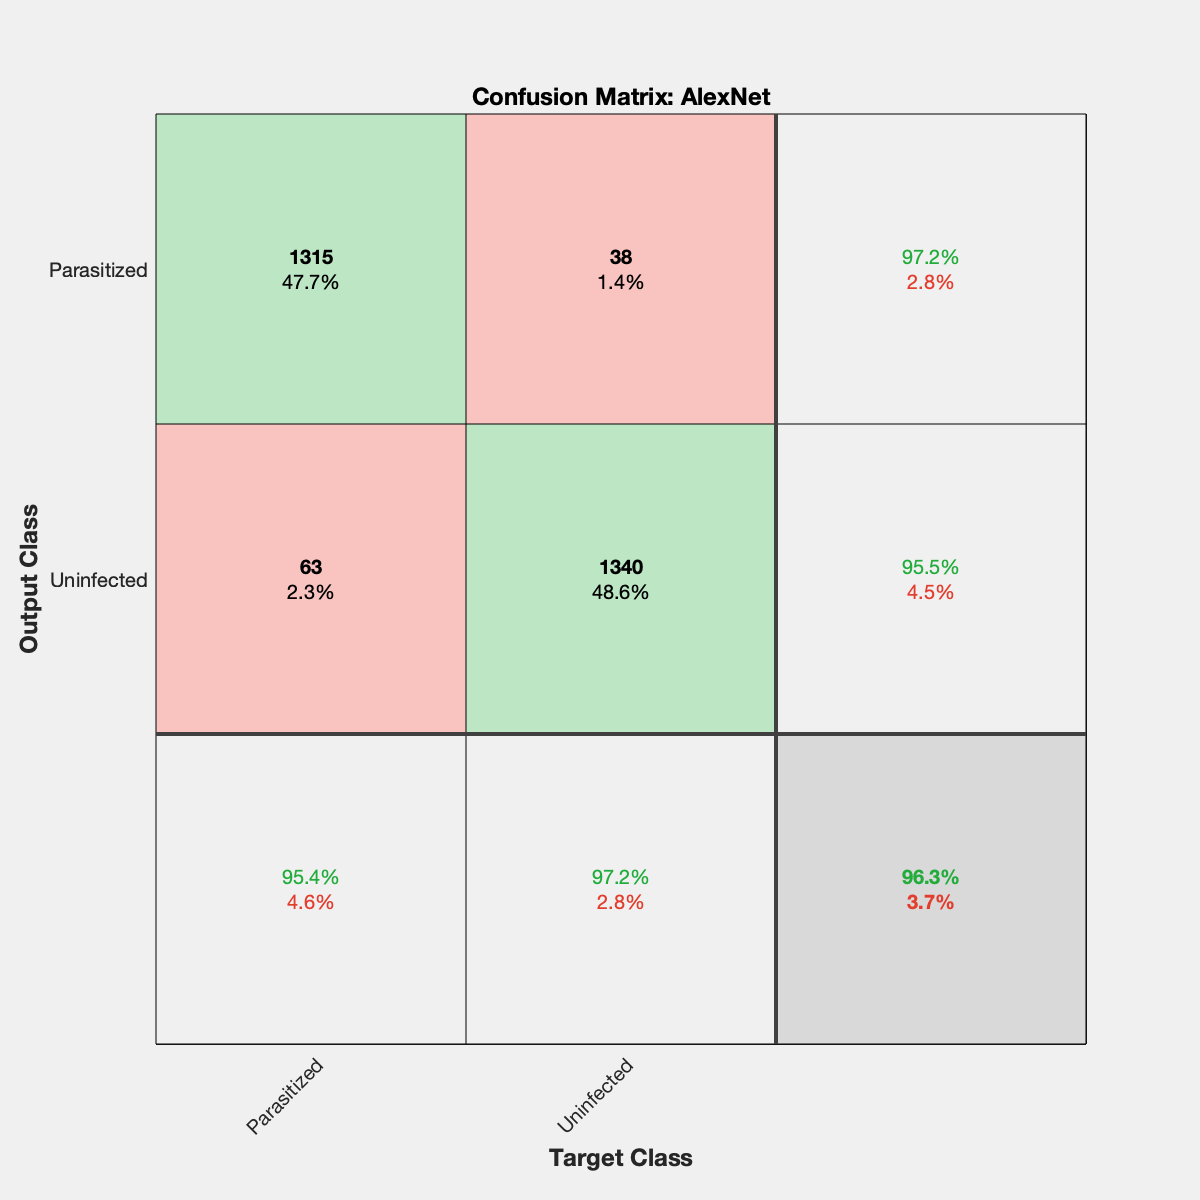

% Actual Labels
actual_labels=imdsTest.Labels;

% Confusion Matrix
figure;
plotconfusion(actual_labels,predicted_labels)
title('Confusion Matrix: AlexNet');

## ROC Curve

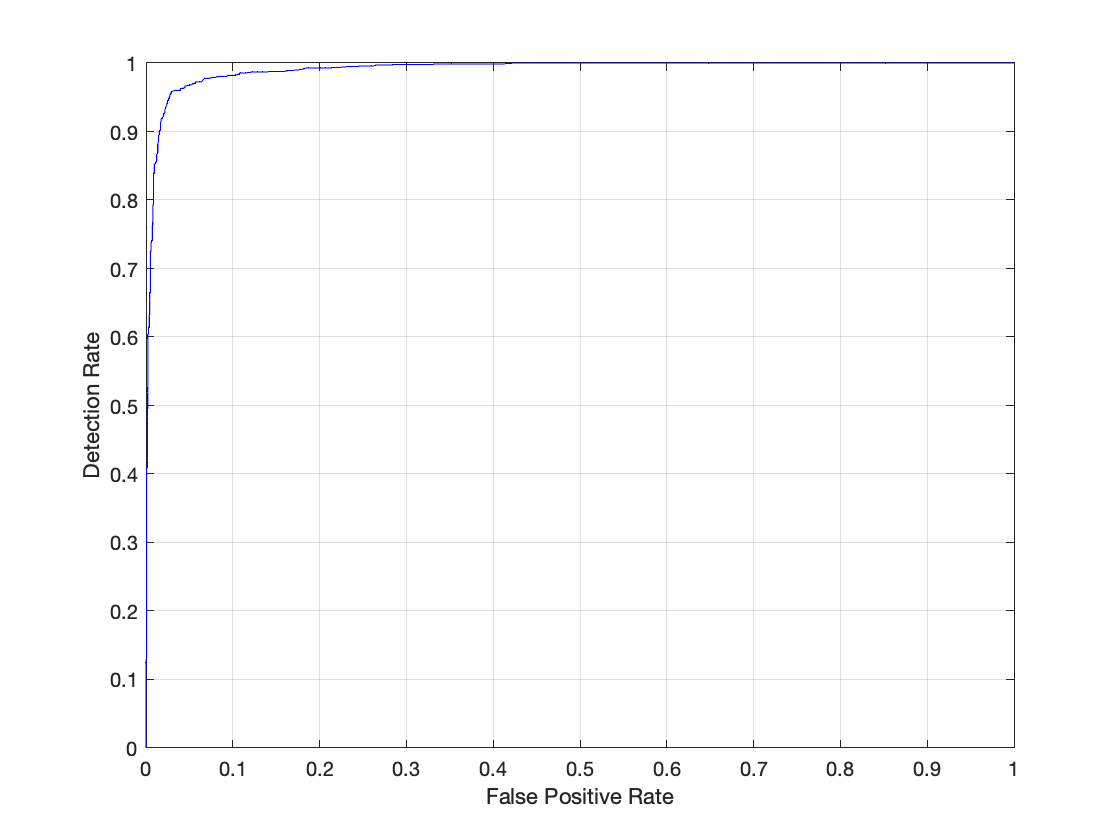

test_labels=double(nominal(imdsTest.Labels));

% ROC Curve - Our target class is the first class in this scenario.
[fp_rate,tp_rate,T,AUC]=perfcurve(test_labels,posterior(:,1),1);
figure;
plot(fp_rate,tp_rate,'b-');hold on;
grid on;
xlabel('False Positive Rate');
ylabel('Detection Rate');


AUC

AUC = 0.9910

Function: Preprocessing Function, Color Constancy

function Iout=preprocess_malaria_images(filename,desired_size)

% Read the Image
I=imread(filename);

% Some images might be grayscale, replicate the image 3 times to
% create an RGB image.

if ismatrix(I)
  I=cat(3,I,I,I);
end

% Conversion to Double for calculation purposes
I=double(I);

% Mean Calculation
Ir=I(:,:,1);mu_red=mean(Ir(:));
Ig=I(:,:,2);mu_green=mean(Ig(:));
Ib=I(:,:,3);mu_blue=mean(Ib(:));
mean_value=(mu_red+mu_green+mu_blue)/3;

% Scaling the Image for Color constancy
Iout(:,:,1)=I(:,:,1)*mean_value/mu_red;
Iout(:,:,2)=I(:,:,2)*mean_value/mu_green;
Iout(:,:,3)=I(:,:,3)*mean_value/mu_blue;

% Converting it back to uint8
Iout=uint8(Iout);

% Resize the image
Iout=imresize(Iout,[desired_size(1) desired_size(2)]);
end

Function: Reshape Image

function Iout = reshape_image(filename,img_size)

I = imread(filename);
Iout=imresize(I,[32 32]);

end

Function: Grayscale and Histogram Equaliztion

function Iout = reshape_grayscale_histeq(filename,img_size)

I=imread(filename);
I=rgb2gray(I);
I=histeq(I);

Iout=imresize(I,img_size);
end